5.1 - Image Manipulation

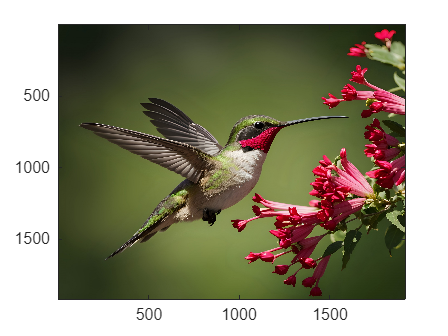

%5.1.1 

% In this step, we will read and image, transform it to double form of
% greyscale, as well as the RGB intensity values

    % Reading rectangle image
        X = imread('square.jpg');
        imagesc(X)

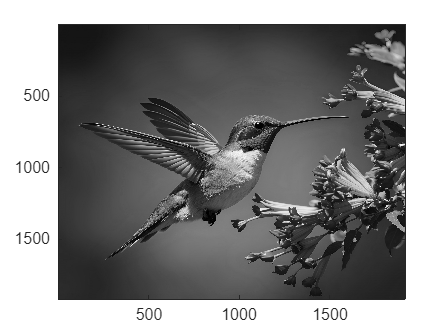

    
    % Convert X matrix to double datatype
        X_double = double(X);
        % Setting Variable that will be used in question below
            R = X_double(:,:,1);
            G = X_double(:,:,2);
            B = X_double(:,:,3);
        
    % Convert to double (data type) greyscale image and read greyscale image
    
        X_gray= X_double(:,:,1)/3.0 + X_double(:,:,2)/3.0 + X_double(:,:,3)/3.0;
            % Side note, this is taking the average of each intensity and
            % linearly combining it into 1 matrix
        imagesc(uint8(X_gray))
        colormap('gray')

        
        X_gray % Intensity values of greyscale matrix

X_gray =    22.0000   22.0000   22.0000   22.0000   22.0000   22.0000   22.0000   22.0000   22.0000   22.0000   22.0000   22.0000   22.0000   22.0000   22.0000   22.0000   22.0000   22.0000   22.0000   22.0000   22.0000   22.0000   22.0000   22.0000   22.0000   21.0000   21.0000   22.0000   22.0000   22.0000   21.0000   20.0000   22.0000   21.0000   21.0000   20.0000   20.0000   20.0000   20.0000   21.0000   20.0000   21.0000   21.0000   21.0000   20.0000   20.0000   21.0000   21.0000   21.0000   21.0000
   22.0000   22.0000   22.0000   22.0000   22.0000   22.0000   22.0000   22.0000   22.0000   22.0000   22.0000   22.0000   22.0000   22.0000   22.0000   22.0000   22.0000   22.0000   22.0000   22.0000   22.0000   22.0000   22.0000   22.0000   22.0000   22.0000   22.0000   22.0000   22.0000   22.0000   21.0000   21.0000   22.0000   21.0000   21.0000   21.0000   20.0000   20.0000   21.0000   21.0000   20.0000   21.0000   21.0000   21.0000   20.0000   20.0000   20.0000   21.0000   20.0000

    
        % Intensity Values of RGB
            % Red
        X_R_Intensity = R

X_R_Intensity =     21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    20    20    21    21    21    20    19    21    20    20    19    19    19    19    20    19    20    20    20    19    19    20    20    20    20
    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    20    20    21    20    20    20    19    19    20    20    19    20    20    20    19    19    19    20    19    19
    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    20    20    20    20    20    20    20    20    20    20    20    19    19    19    20    20    20    19    20    20
    21    21    21    21    21    21    21    21    21    21    21    21    21   

            % Green
        X_G_Intensity = G

X_G_Intensity =     29    29    29    29    29    29    29    29    29    29    29    29    29    29    29    29    29    29    29    29    29    29    29    29    29    28    28    29    29    29    28    27    29    28    28    27    27    27    27    28    27    28    28    28    27    27    28    28    28    28
    29    29    29    29    29    29    29    29    29    29    29    29    29    29    29    29    29    29    29    29    29    29    29    29    29    29    29    29    29    29    28    28    29    28    28    28    27    27    28    28    27    28    28    28    27    27    27    28    27    27
    29    29    29    29    29    29    29    29    29    29    29    29    29    29    29    29    29    29    29    29    29    29    29    29    29    29    29    29    29    29    28    28    28    28    28    28    28    28    28    28    28    27    27    27    28    28    28    27    28    28
    29    29    29    29    29    29    29    29    29    29    29    29    29   

            % Blue
        X_B_Intensity = B

X_B_Intensity =     16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    15    15    16    16    16    15    14    16    15    15    14    14    14    14    15    14    15    15    15    14    14    15    15    15    15
    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    15    15    16    15    15    15    14    14    15    15    14    15    15    15    14    14    14    15    14    14
    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    15    15    15    15    15    15    15    15    15    15    15    14    14    14    15    15    15    14    15    15
    16    16    16    16    16    16    16    16    16    16    16    16    16   

        % Creating new Image
            imwrite(uint8(X_gray),'5.1.1_square.jpg')

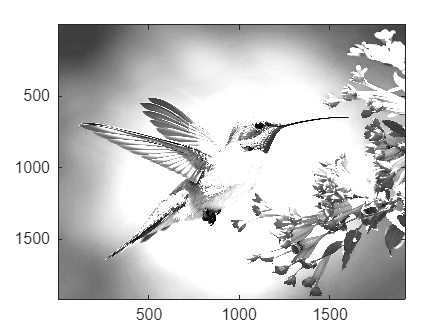

% 5.1.2

% In this step we need to change the exposure of the image to look more
% whited out. My idea is to multiply the intesity of the RBG matrixes by a
% scalar multiple (somthing > 1) to achieve this.
    exposure = 3;
    % Scaling R by 3
        X_R_Whitedout = exposure .* R;
    % Scaling R by 3
        X_G_Whitedout = exposure .* G;
    % Scaling R by 3
        X_B_Whitedout = exposure .* B;
    % Combining these back into a greyscale image
        X_gray_Whitedout = X_R_Whitedout /3.0 + X_G_Whitedout /3.0 + X_B_Whitedout /3.0;
        imagesc(uint8(X_gray_Whitedout))
        colormap('gray')

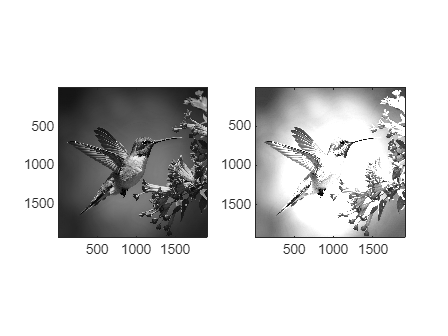

    % Creating new image
        imwrite(uint8(X_gray_Whitedout),'5.1.2_square.jpg')
    % Create a subplot of both greyscale images next to each other.
        subplot(1,2,1) % Normal Grayscale
        imagesc(uint8(X_gray))
        colormap('gray')
        axis square
        
        subplot(1,2,2) % Grayscale with greater contrast
        imagesc(uint8(X_gray_Whitedout))
        colormap('gray')
        axis square

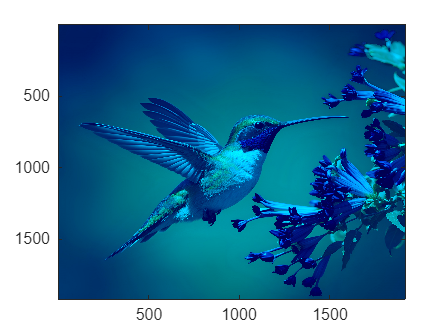

%5.1.3

% In this section, we are eliminating the red from the image and adding 80
% to the blue value intensity.
    
    % Creating Elim red
        X_elim_red = double(X);
    % Setting R intensity = 0
        X_elim_red(:,:,1) = 0;
    % Setting G intensity = G
        X_elim_red(:,:,2) = X_elim_red(:,:,2);
    % Setting B intensity = 80 + B
        X_elim_red(:,:,3) = X_elim_red(:,:,3) + 80;
    % Assembling image 
        figure;
        imagesc(uint8(X_elim_red))

    % Creating new image with changes
        imwrite(uint8(X_elim_red),'5.1.3_square.jpg')

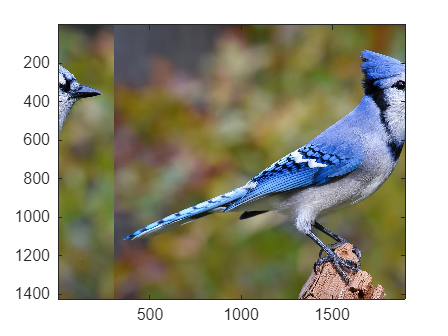

%5.1.5

% We are Shifting the rectangle by 306 pixels

% Thing to know, the permutation matrix must have the same touching
% dimension as the thing its multiplying. 
% For Example
    % A Vertical shift on a non square matrix image looks like this.T * X. 
    % The T columns size must match the X row size.
    % For a horizontal shift, X * T, The T rows must match the X column size

% Read Rectangle
    Xr = imread('rectangle.jpg');

% Code from section 2, modified to work with rectangles
    X_hshift = double(Xr);    
    [m,n,~] = size(Xr);
    r = 306;                    % shift RIGHT by r columns   
    E = eye(n);
    T = zeros(n);
    
    % left r columns of T get the LAST r columns of E
        T(:,1:r) = E(:,n-r+1:n);
    
    % remaining columns of T get the FIRST n-r columns of E
        T(:,r+1:n) = E(:,1:n-r);

    % Convert T to floating point
        T = double(T);

    % Since color, need to multiply each 2d vector (R,G,B) by shift
        % R Shift
            X_hshift(:,:,1) = X_hshift(:,:,1) * T;
        % G Shift 
            X_hshift(:,:,2) = X_hshift(:,:,2) * T;
        % B Shift
            X_hshift(:,:,3) = X_hshift(:,:,3) * T;
            
    % Print shifted image
        imagesc(uint8(X_hshift))

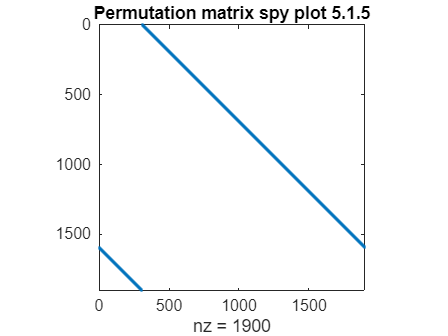

    % Creating new image with changes
        imwrite(uint8(X_hshift),'5.1.5_rectangle.jpg')

% Using Spy on permutation matrix
    f = figure(2);
    spy(T);
    title('Permutation matrix spy plot 5.1.5')
% Export image as jpg
    exportgraphics(f, '5.1.5_rectangle_spy.jpg', 'Resolution', 300);     % high-DPI jpg

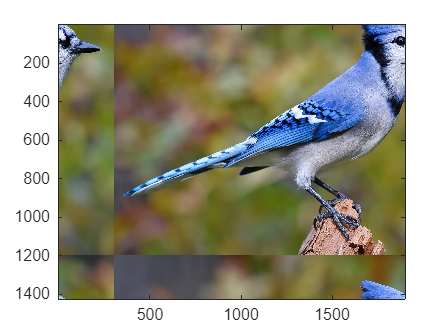

%5.1.6 

% In this problem, we need to shift the image vertically and horizontally.
% I will take from last problem for horizontal, and just change the rows of
% the T matrix from the Eye matrix instead of columns


% Creating image matrix to shift 
    X_h_v_shift = double(Xr);    
    [m,n,~] = size(Xr);

% Shifting Right by 306
   % horizontal RIGHT shift by 306
        rh = 306;
        Ec = eye(n); Tcol = zeros(n);
        Tcol(:,1:rh)   = Ec(:,n-rh+1:n);
        Tcol(:,rh+1:n) = Ec(:,1:n-rh);
    % vertical UP shift by 230
        rv = 230;
        Er = eye(m); Trow = zeros(m);
        Trow(1:m-rv,:)     = Er(1+rv:m,:);   % up: top gets rows rv+1..m
        Trow(m-rv+1:m,:)   = Er(1:rv,:);   % wrap: bottom gets rows 1..rv
    % Applying Shifts
        % R Shift
            X_h_v_shift(:,:,1) = Trow * X_h_v_shift(:,:,1) * Tcol;
        % G Shift 
            X_h_v_shift(:,:,2) = Trow * X_h_v_shift(:,:,2) * Tcol;
        % B Shift
            X_h_v_shift(:,:,3) = Trow * X_h_v_shift(:,:,3) * Tcol;
        % Print shifted image
            imagesc(uint8(X_h_v_shift))

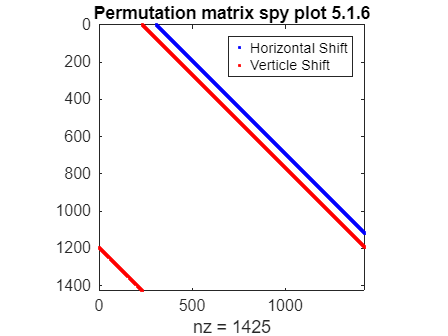


    % Using Spy on permutation matrix
        f = figure(3);
        spy(Tcol,'b',5);
        hold on
        spy(Trow,'r',5);
        title('Permutation matrix spy plot 5.1.6')
        legend('Horizontal Shift','Verticle Shift')
        hold off
        
    
    % Creating new image with changes
        imwrite(uint8(X_h_v_shift),'5.1.6_rectangle.jpg')
    % Export image as jpg
        exportgraphics(f, '5.1.6_rectangle_spy.jpg', 'Resolution', 300);     % high-DPI jpg    

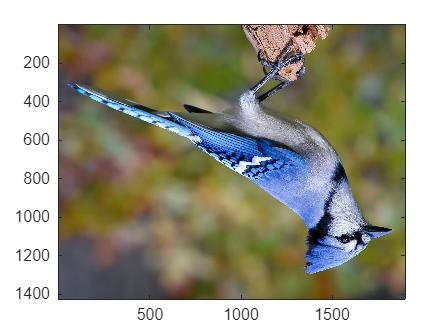

%5.1.7

% Need to flip image upside down. 
% After some research, I found something called an "Exchange matrix". It is
% the identity matrix flipped, so it is a diagonal from top right to bottom left 

% Creating image matrix to flip
    X_flip = double(Xr);
% Create Ident matrix and get size
    [m,n,~] = size(Xr);
    % Creating Rows exhange matrix
        EX_rows = eye(m);
        EX_rows = EX_rows(end:-1:1,:); % this line reorders the Rows from [1, 2,...,n] to [n, n-1,...1].
                                      % "end:-1:1" this sets the rows,
                                      % starting at "end", decrementing by
    
    % Flip image by multipying the row shift on left
    % right, on each color matrix 
        for k = 1:3
            X_flip(:,:,k) = EX_rows * X_flip(:,:,k);
        end
    % Print Shifted image
        imagesc(uint8(X_flip));

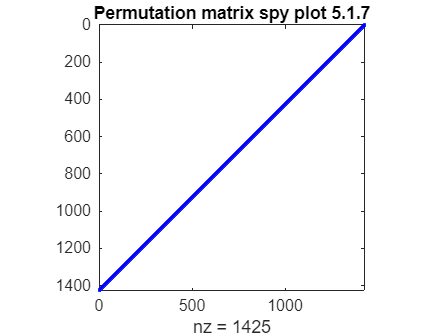

    % Create image file
        imwrite(uint8(X_flip),'5.1.7_rectangle.jpg')
    % Spy plot of exchange matrix
        f = figure(4);
        spy(EX_rows,'b',5);
        title('Permutation matrix spy plot 5.1.7')
    % Create image from spy plot
        exportgraphics(f, '5.1.7_rectangle_spy.jpg', 'Resolution', 300);     % high-DPI jpg   

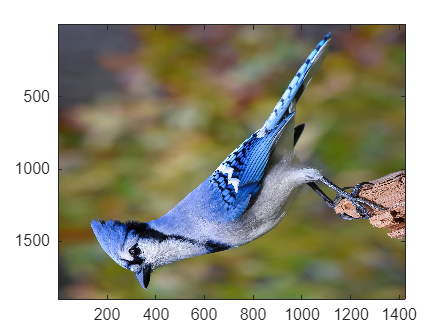

% 5.1.8

% In this section we need to see what transposing the image does.
% Mathematically, it replaces the rows and columns. I think it is going to
% rotate the image, we will see though

% Creating rectangle matrix to transpose
    Xd = double(Xr);
    [m,n,~] = size(Xd);
    Xt = zeros(n,m,3); 

    % Transpose matrix, each color at avtime 
        for k = 1:3
            Xt(:,:,k) = Xd(:,:,k).'; % Transposing image
        end
    % Print new image
        imagesc(uint8(Xt));

    % Create image file
        imwrite(uint8(Xt),'5.1.8_rectangle.jpg')

% 5.1.9

%